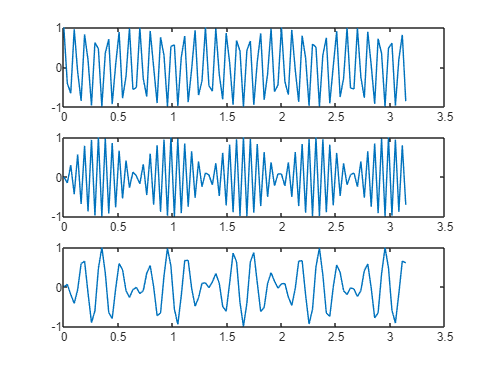

clc, close all; clear;

x1 = @(t) cos(20*pi.*t);
x2 = @(t) cos(30*pi.*t + pi/2);
x3 = @(t) x1(t) .* x2(t);

t = linspace(0, 1*pi, 100);

figure;
subplot(311);
plot(t, x1(t));
subplot(312);
plot(t, x2(t));
subplot(313);
plot(t, x3(t));

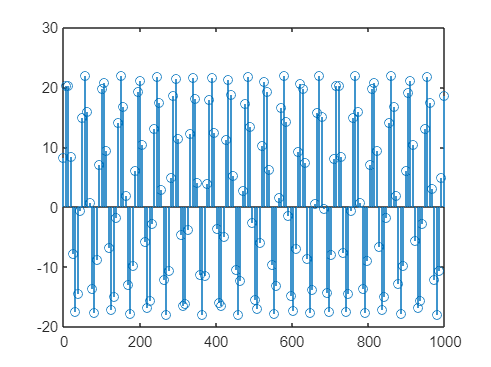

clc, close all; clear;

n = 0:2*pi:1000;
x = 20*cos((8*pi*n)-0.4*pi)+2;
stem(n,x)

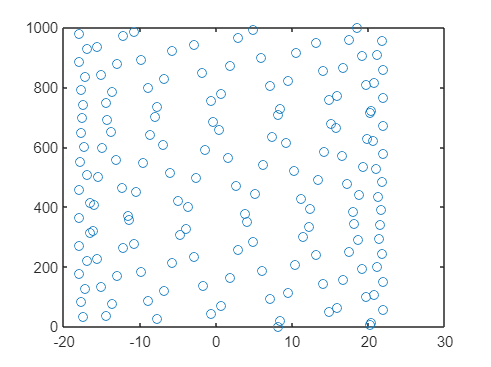

plot(x,n,'o')

clc, close all; clear;

x1 = 1-(1/2j)*(exp(j*pi/3))

x1 = 0.5670 + 0.2500i

x2 = 1+(1/2j)*(exp(-j*pi/3))

x2 = 0.5670 - 0.2500i


[theta1,rho1] = cart2pol(real(x1), imag(x1))

theta1 = 0.4153

rho1 = 0.6197

[theta2,rho2] = cart2pol(real(x2), imag(x2))

theta2 = -0.4153

rho2 = 0.6197

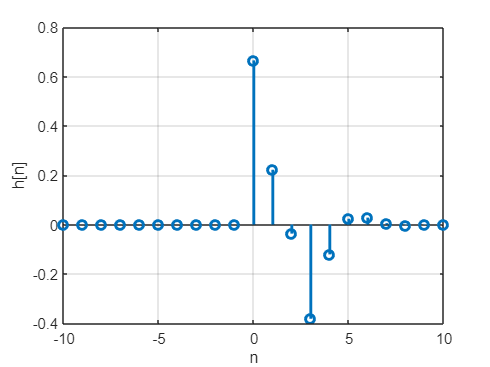

clc, close all; clear;

a = [3 -1 1/2]; 
b = [2 0 0 -1];
n = -10:10;
h= impz(b, a, n);
stem(n, h, 'Linewidth',2); grid; xlabel('n'); ylabel('h[n]');

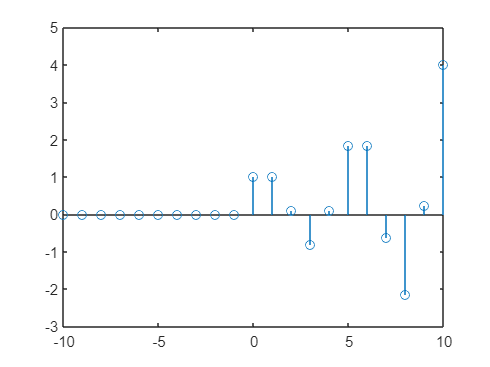

clc, close all; clear;
b = 1;
a = [1 -1 0.9 0 -1];
n = -10:10;
[h, t] = impz(b, a, n);
z = filter(b, a, n);

figure;
stem(t, h);

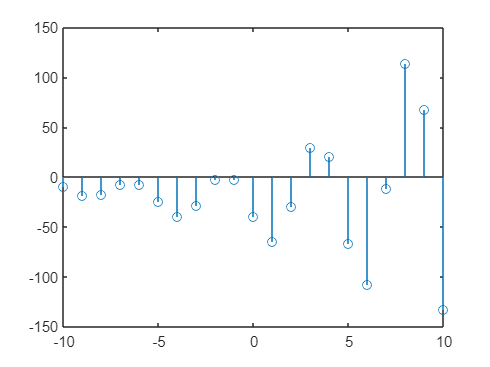


figure;
stem(n, z)

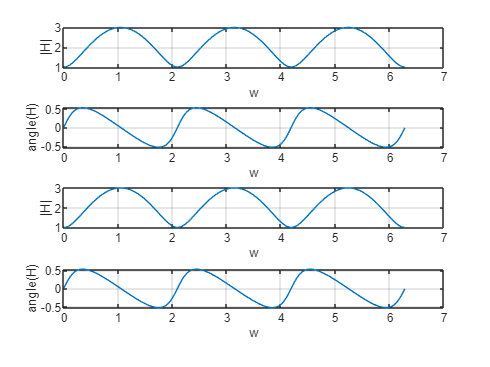

clc, clear, close all;

H = @(w) 2-exp(-j*3*w);
w = 0:0.01:2*pi;

subplot(411); plot(w, abs(H(w))); xlabel('w'); ylabel('|H|'); grid; 
subplot(412); plot(w, angle(H(w))); xlabel('w'); ylabel('angle(H)'); grid;

mag_H = sqrt((2-cos(3*w)).^2 + (sin(3*w)).^2);
angle_H = atan((sin(3*w)) ./ (2-cos(3*w)));

subplot(413); plot(w, mag_H); xlabel('w'); ylabel('|H|'); grid;
subplot(414); plot(w, angle_H); xlabel('w'); ylabel('angle(H)'); grid;

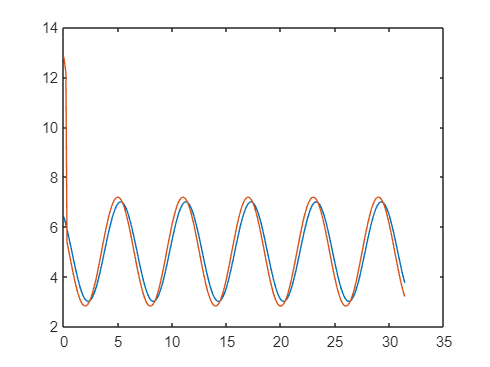

clc, clear, close all;

n = 0:0.1:10*pi;
x = 5 + 2*cos((pi/3).*n + pi/4);
b = 1;
% h[n] = 2delta[n] - delta[n-3] 
% y[n] = 2x[n] - x[n-3] 
a = [2 0 0 -1];
y = filter(a, b, x);
plot(n,x)
hold on
plot(n,y)
hold off

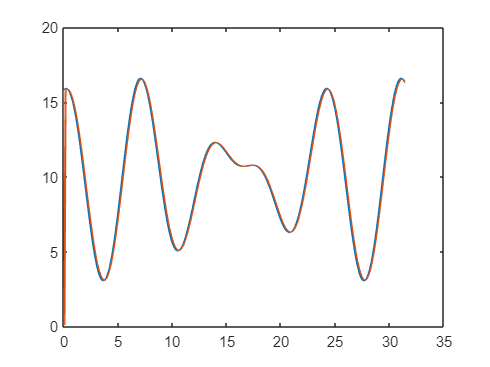

clc, clear, close all;

n = 0:0.1:10*pi;
x = 10 + 4*cos((pi/4).*n + pi/8) + 3*cos((pi/3).*n - pi/4);
b = 1;
% H(e^jw) = 1 - e^-jw + e^-j2w
% h[n] = delta[n] - delta[n-1] + delta[n-2] 
a = [1 -1 1];
% y[n] = ?
y = filter(a, b, x);
plot(n,x)
hold on
plot(n,y)
hold off

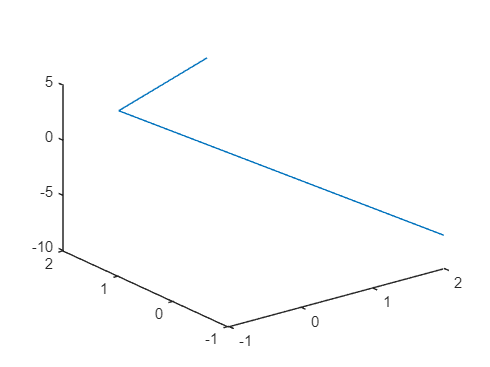

clc, clear, close all;

v1 = [1 -1 2];
v2 = [2 1 -1];
v3 = [4 5 -7];
% x = v1(1)*v2(1)*v3(1)
% y = v1(2)*v2(2)*v3(2)
% z = v1(3)*v2(3)*v3(3)

plot3(v1, v2, v3)

A = [2 0 0;
     0 1 2;
    0 2 5]

A =      2     0     0
     0     1     2
     0     2     5


try chol(A)
    disp('Matrix is symmetric positive definite.')
catch ME
    disp('Matrix is not symmetric positive definite')
end

ans =     1.4142         0         0
         0    1.0000    2.0000
         0         0    1.0000


Matrix is symmetric positive definite.


d = eig(A)

d =     0.1716
    2.0000
    5.8284


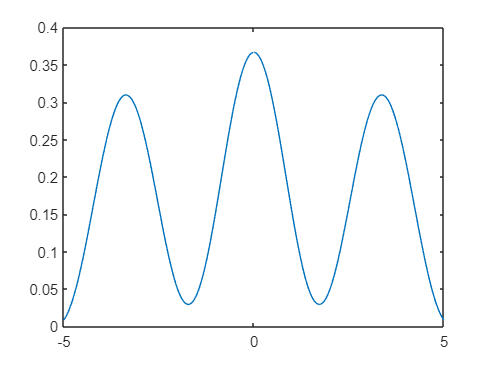

clc, clear, close all;

n = -5:0.01:5;
h = (2.*sin(pi.*n/10)./(pi.*n)) + (sin(2*pi.*n/3)./(pi.*n)) - (sin(pi.*n/2)./(pi.*n));
plot(n,h)

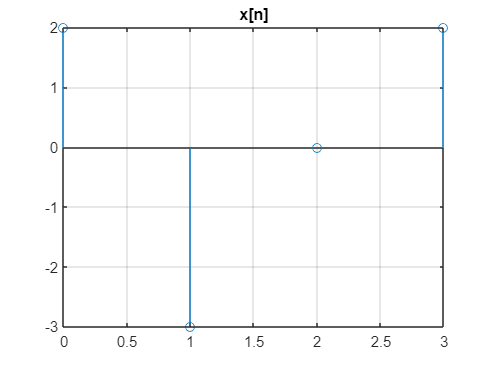

clc, clear; close all;

x = [2 -3 0 2];
stem(0:length(x)-1,x); title('x[n]'); grid;

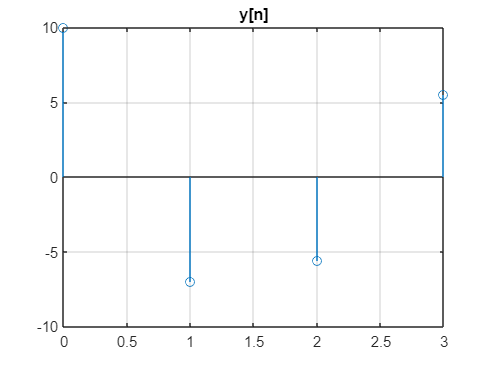


a = [1 -0.8];
b = 5;
y = filter(b, a, x); 
stem(0:length(y)-1,y); title('y[n]'); grid;

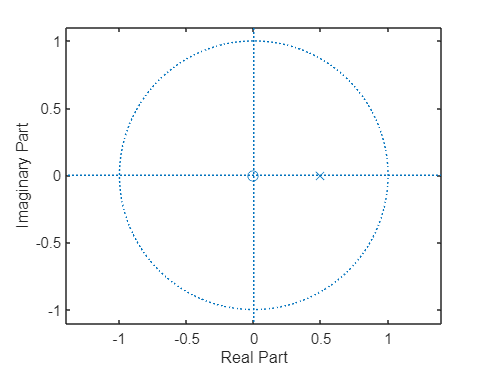

clc, clear; close all;

% H(z) = 1/(1-0.5*z^-1)
B = 1;
A = [1, -0.5];
zplane(B, A)

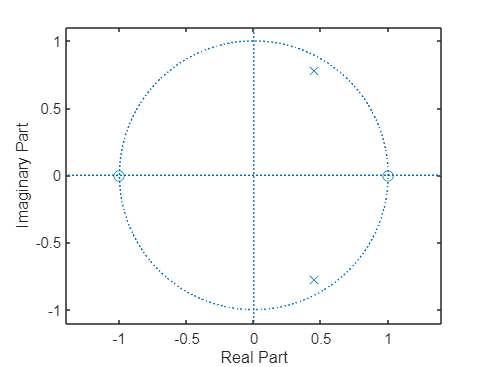

% H(z) = (1-z^-2)/(1 - 0.9^z-1 + 0.81z^-2)
B = [1 0 -1];
A = [1 -0.9 0.81];
zplane(B, A)

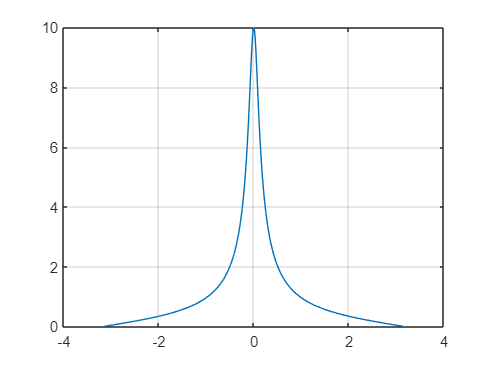

clc, clear; close all;

w = -pi:0.01:pi;
H = freqz([1/2 1/2], [1 -0.9], w);   
plot(w,abs(H));grid

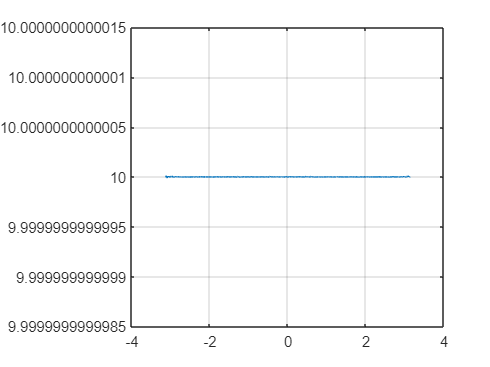

H2 = freqz([9 10], [1 0.9], w);
plot(w,abs(H2));grid